Homework 6

Shaobo Wang

Question 1.

clear;clc

(a) 

s = tf("s");

The "true" plant model can be seen as an element in a set of uncertainty models. The nominal model is choose to be a lower-order and non-delay model. 

Gtrue = 3*exp(-0.1*s)/(2*s+1)/(0.1*s+1)^2;
Gnorm = 3/(2*s+1); 

Based on additive uncertainty model:


$$G_p = G_{norm}+W_A\Delta_A\\
W_A\Delta_A = G_p-G_{norm}\\
\|\Delta_A\|_{\infty}\leq1\Rightarrow |W_A|\geq G_p-G_{norm}$$


In order to find the minimized possible $W_A$, then $W_A = G_{true}-G_{norm}$:

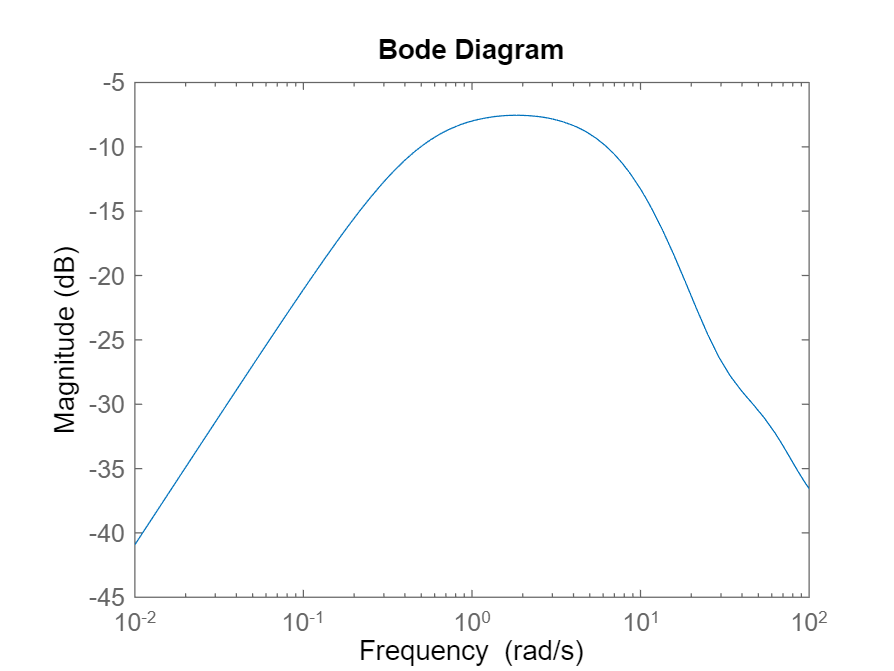

WA = Gtrue - Gnorm;
bodemag(WA);

(b)

clear;clc

A simplified model is choosed to be the nominal model. Therefore, the actual model can be written as the uncertain model with this nominal model under the largest uncertainty.

s = tf('s');
Gactual = 10*(-0.5*s+1)/(6*s+1)/(0.2*s+1)/(20*s+1);
Gnorm = 10/(6*s+1);

Based on multiplicative uncertainty assumption:


$$G_p = G_{norm}(1+W_I\Delta)\\
W_I\Delta = \frac{G_p}{G_{norm}}-1$$


Therefore, 


$$W_I = \frac{G_{actual}}{G_{norm}}-1=\frac{-0.5s+1}{(0.2s+1)(20s+1)}-1$$


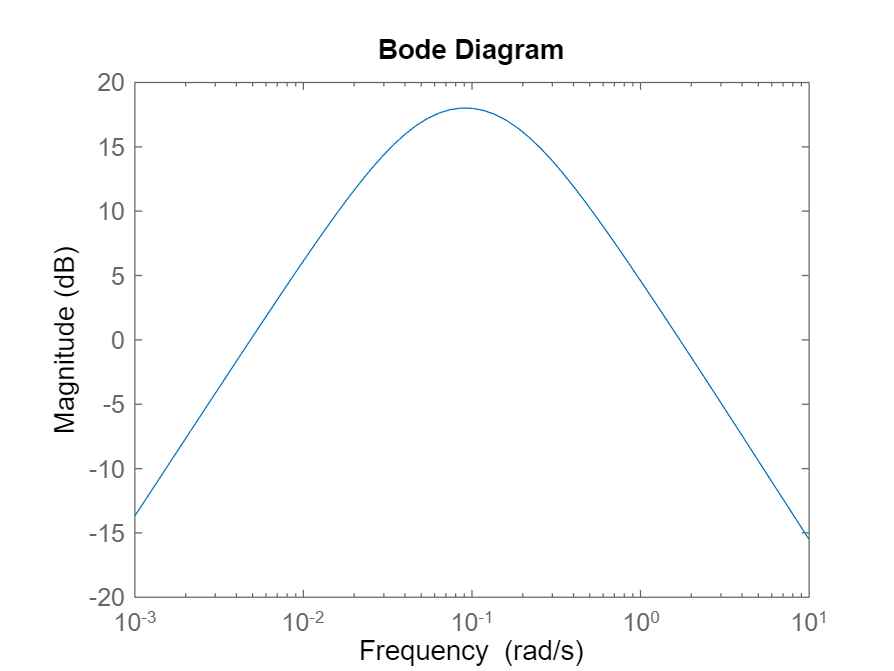

WI = Gactual-Gnorm;
bodemag(WI);

(c) 

a. 


$$\begin{cases}
z = w_Au\\
y = w+Gu
\end{cases}
\Rightarrow
\left[
\matrix{z\cr y}
\right]=
\left[
\matrix{0&w_A\cr 1&G}
\right]
\left[
\matrix{w\cr u}
\right]
\Rightarrow
H = 
\left[
\matrix{0&w_A\cr 1&G}
\right]$$


b.


$$\begin{cases}
z = w_Iu\\
y = G(w+u)
\end{cases}
\Rightarrow
\left[
\matrix{z\cr y}
\right]=
\left[
\matrix{0&w_I\cr G&G}
\right]
\left[
\matrix{w\cr u}
\right]
\Rightarrow
H = 
\left[
\matrix{0&w_I\cr G&G}
\right]$$


c.


$$\begin{cases}
z = w_OGu\\
y = w+Gu
\end{cases}
\Rightarrow
\left[
\matrix{z\cr y}
\right]=
\left[
\matrix{0&w_OG\cr 1&G}
\right]
\left[
\matrix{w\cr u}
\right]
\Rightarrow
H = 
\left[
\matrix{0&w_OG\cr 1&G}
\right]$$


d.


$$\begin{cases}
z = Gw_{iA}w+Gu\\
y = Gw_{iA}w+Gu
\end{cases}
\Rightarrow
\left[
\matrix{z\cr y}
\right]=
\left[
\matrix{Gw_{iA}&G\cr Gw_{iA}&G}
\right]
\left[
\matrix{w\cr u}
\right]
\Rightarrow
H = 
\left[
\matrix{Gw_{iA}&G\cr Gw_{iA}&G}
\right]$$


e.


$$\begin{cases}
z = w_{iI}w+u\\
y = Gw_{iI}w+Gu
\end{cases}
\Rightarrow
\left[
\matrix{z\cr y}
\right]=
\left[
\matrix{w_{iI}&1\cr Gw_{iI}&G}
\right]
\left[
\matrix{w\cr u}
\right]
\Rightarrow
H = 
\left[
\matrix{w_{iI}&1\cr Gw_{iI}&G}
\right]$$


f.


$$\begin{cases}
z = w_{iO}w+Gu\\
y = w_{iO}w+Gu
\end{cases}
\Rightarrow
\left[
\matrix{z\cr y}
\right]=
\left[
\matrix{w_{iO}&G\cr w_{iO}&G}
\right]
\left[
\matrix{w\cr u}
\right]
\Rightarrow
H = 
\left[
\matrix{w_{iO}&G\cr w_{iO}&G}
\right]$$


Question 2

(a)

clear;clc

Import two uncertain models:

HDDModel_DS_Uncertain

Find multiplicative uncertainty models that covers all cases:

VCMvec = usample(VCM,100);
PZTvec = usample(PZT,100);

[VCMp,VCM_info] = ucover(VCMvec,VCM.NominalValue,2);
[PZTp,PZT_info] = ucover(PZTvec,PZT.NominalValue,2);

The final weight for each model:

tf(VCM_info.W1)

ans =
 
  22.89 s^2 + 1.674e07 s + 5.801e07
  ---------------------------------
     s^2 + 4.192e05 s + 1.067e10
 
Continuous-time transfer function.



tf(PZT_info.W1)

ans =
 
  43.89 s^2 + 3.649e05 s + 3.975e07
  ---------------------------------
       s^2 + 4801 s + 2.455e09
 
Continuous-time transfer function.



The uncertainty weight performance:

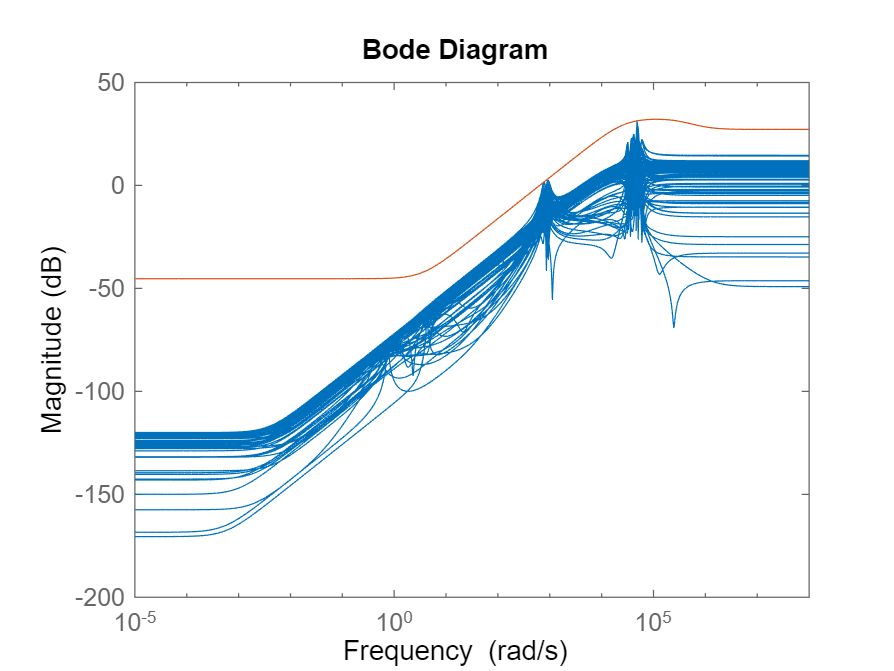

bodemag((VCMvec-VCM.NominalValue)/VCM.NominalValue,VCM_info.W1);

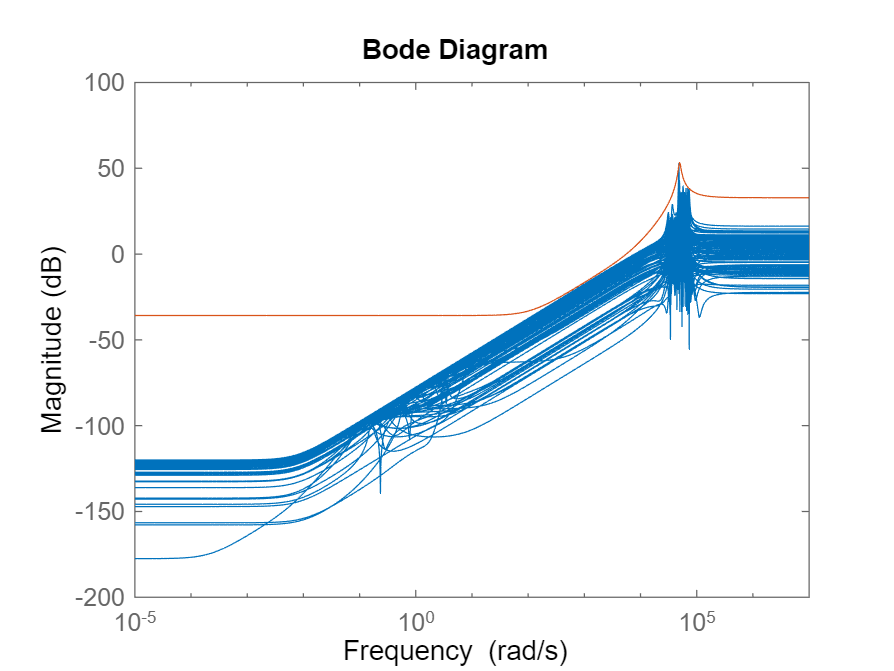

bodemag((PZTvec-PZT.NominalValue)/PZT.NominalValue,PZT_info.W1);

As shown in the plotted result, the weight is too conservative in the lower frequency zone. 

(b)

Design controller for VCM:

wh = 1000;
wl = 0;
w_try = wh;
w_new = 1/2*(wh+wl);
while(abs(w_new-w_try)>.001)  %Stopping criterion
    w_try = w_new;
    Wp = makeweight(1000,w_try,1/2);
    [K_VCM,CL,GAM] = mixsyn(VCM,Wp,[],VCM_info.W1);
    if GAM<1
        wl = w_try;  %We're not agressive enough
    else
        wh = w_try;  %We're too agressive
    end
    w_new = 1/2*(wh+wl);
end

Plot the uncertain sensitivity function vs. the performance weight:

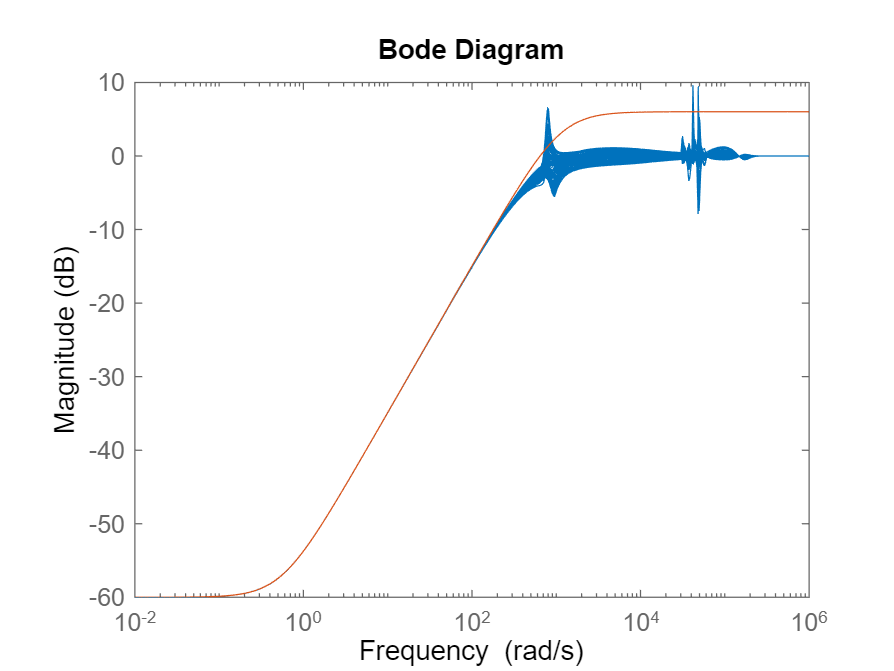

S_VCM = 1-feedback(VCM*K_VCM,1);
S_VCMvec = usample(S_VCM,100);
bodemag(S_VCMvec,1/Wp);

As the plot showed, the uncertain sensitivity function with $\gamma<1$ didn't make sure RP. 

(c) 

VCMn = VCM.NominalValue;
PZTn = PZT.NominalValue;
Wvcm = VCM_info.W1;
Wpzt = PZT_info.W1;

wh = 1000;
wl = 0;
w_try = wh;
w_new = 1/2*(wh+wl);
k = 1;
while(abs(w_new-w_try)>.001)  %Stopping criterion
    w_try = w_new;
    Wp = makeweight(1000,w_try,1/2);
    systemnames = 'VCMn PZTn Wvcm Wpzt Wp';
    inputvar = '[udv;udp;r;uv;up]';
    outputvar = '[Wvcm;Wpzt;Wp;udv+udp+VCMn+PZTn;r-udv-udp-VCMn-PZTn]';
    
    input_to_VCMn = '[uv]';
    input_to_PZTn = '[up]';
    input_to_Wp = '[r-udv-udp-VCMn-PZTn]';
    input_to_Wvcm = '[VCMn]';
    input_to_Wpzt = '[PZTn]';
    
    cleanupsysic = 'yes';  
    P = sysic;
    [K,CL,GAM(k)] = hinfsyn(P,1,2);

    if GAM(k)<3.5
        wl = w_try;  %We're not agressive enough
    else
        wh = w_try;  %We're too agressive
    end
    w_new = 1/2*(wh+wl);
    k = k+1;
end

Plot values of $\gamma$ through iteration:

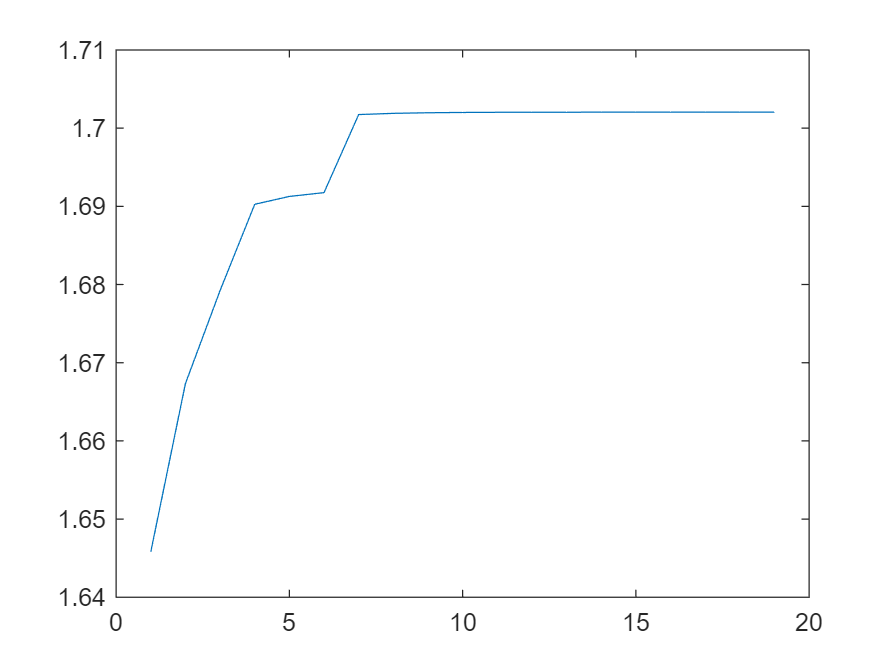

plot(1:length(GAM),GAM);

Plot uncertain sensitivity function vs. performance weight:

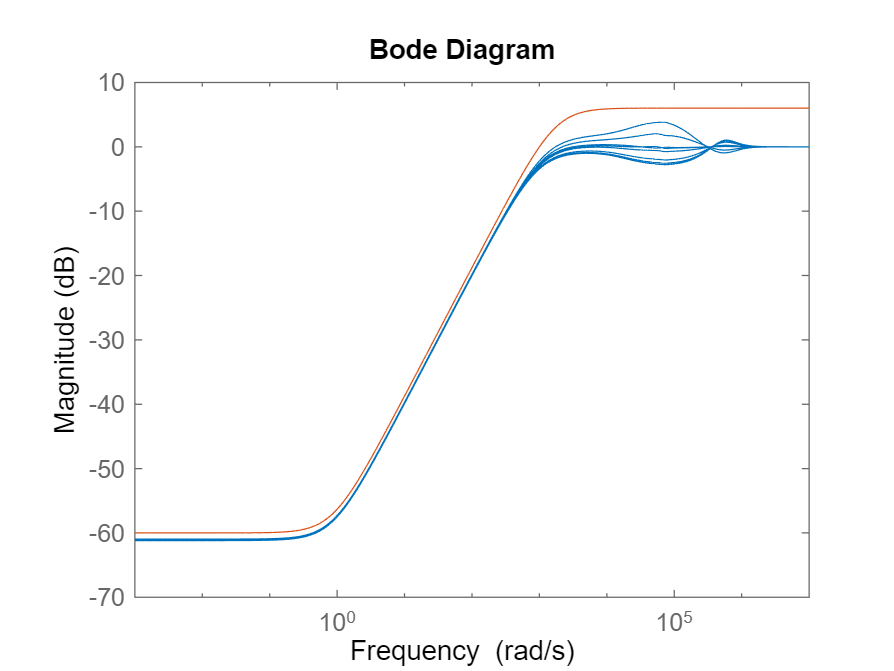

G = [VCMp,PZTp];
S = 1/(1+G*K);
Svec = usample(S,10);
bodemag(Svec,1/Wp);

Question 3

(a)

clear;clc

Load a vector of responses:

load("responses.mat");
s = tf('s');

The nominal plant model is:

A = [-0.0226,-36.6,-18.9,-32.1;0,-1.9,0.983,0;0.0123,-11.7,-2.63,0;0,0,1,0];
B = [0,0;-0.414,0;-77.8,22.4;0,0];
C = [0,57.3,0,0;0,0,0,57.3];
D = [0,0;0,0];
Gnorm = ss(A,B,C,D);

Fit the sampling responses as an uncertain model:

[Gp,info] = ucover(Gp_samples,Gnorm,[2,2]);
Wdel = info.W1;

Plot the uncertainty weight vs. the sampling relative error:

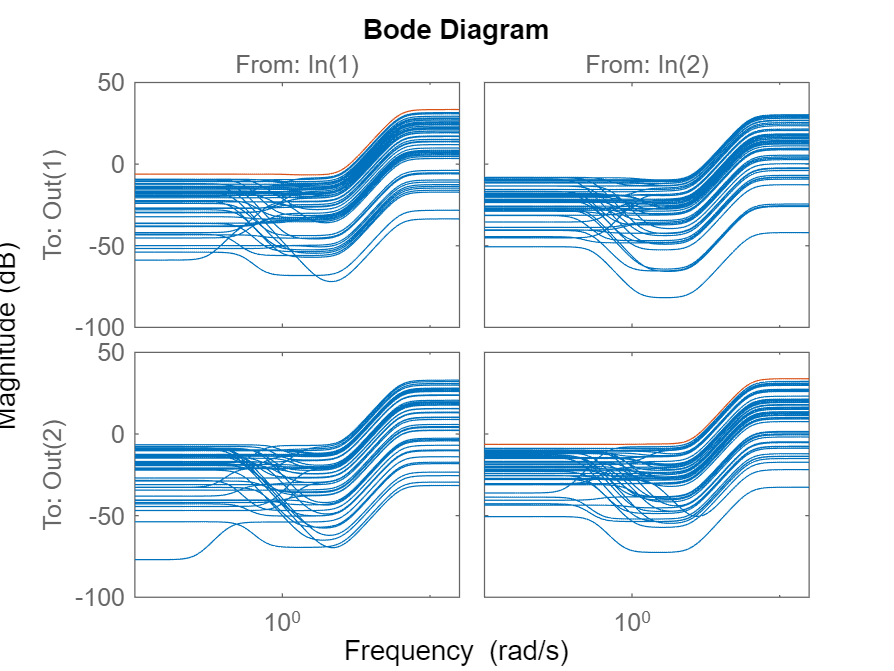

relerr = Gnorm\Gp_samples-eye(2); 
bodemag(relerr,Wdel);

As shown in the plot, ucover assume only diagnol weight for uncertainty. But it fit well with the diagonal terms.

(b)

Wp = [(s+3)/(s+0.03),0;0,0.5*(s+3)/(s+0.03)];
Wn = [2*(s+1.28)/(s+320),0;0,2*(s+1.28)/(s+320)];

Use the synthesis form to do controller design:

systemnames = 'Gnorm Wdel Wp Wn';
inputvar = '[p{2};d{2};n{2};u{2}]';
outputvar = '[Wdel;Wp;Gnorm+d+Wn]';

input_to_Gnorm = '[p+u]';
input_to_Wdel = '[u]';
input_to_Wp = '[d+Gnorm]';
input_to_Wn = '[n]';
cleanupsysic = 'yes';  
P = sysic;
[K,CL,GAM] = hinfsyn(P,2,2);

Plot the sensitivity function:

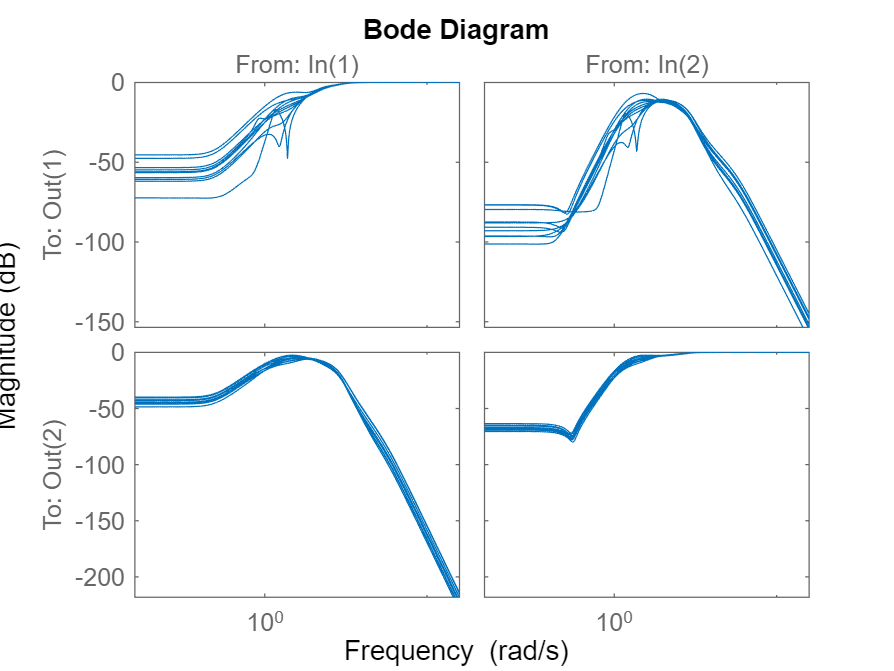

S = eye(2)-feedback(Gp*K,eye(2));
Svec = usample(S,10);
bodemag(Svec);

First check nominal stability:

isNS = isstable(P)

isNS = logical
   1


Use the analysis form to check NP:

N = lft(P,K);
isNP = norm(N(2,2),'inf')<1

isNP = logical
   1


Rebuild generalized plant with uncertain model:

systemnames = 'Gp Wp Wn';
inputvar = '[d{2};n{2};u{2}]';
outputvar = '[Wp;Gp+d+Wn]';

input_to_Gp = '[u]';
input_to_Wp = '[d+Gp]';
input_to_Wn = '[n]';
cleanupsysic = 'yes';  
Phat = sysic;

Nhat = lft(Phat,K);
[perfmarg, robg_wcu] = robgain(Nhat,1);
isRP = 1/perfmarg.LowerBound<1

isRP = logical
   0


[stabmarg,robs_wcu] = robstab(Nhat);
isRS = 1/stabmarg.LowerBound<1

isRS = logical
   1


isRS_con = norm(N(1,1),'inf')<1  % conservative

isRS_con = logical
   1


Therefore, the robust performance is not met, but the robust stability is met.